# Filter_cells

The function *filter_cells *filters the cells/bins and the genes that do not accomplish conditions,from binned data

**Input: **Matisse object (it can be both cells or bins) 

**Matisse parameters: **some parameters need to be adjusted before filtering:

            -BINS.FC_MAX_counts_cell: maximum number of spots that can be in a cell

            -BINS.FC_MIN_counts_cell: minimum number of spots that can be in a cell

            - BINS.FC_MIN_counts_gene: minimum number of reads needed for a specific gene

**Output:** Matisse object with filtered data

**Example**

Here you have the example of how to use the function. First we load the bins, summarized in a matisse object

load ('data\Matisse objects\bins_mousebins.mat');

Then we adjust the parameters starting with FC:

BINS.FC_MAX_counts_cell=5000;
BINS.FC_MIN_counts_cell=50;
BINS.FC_MIN_counts_gene=30;

Then we run the function

Initial number of genes included:  114
Initial number of cells/bins included: 3462
FILTERS APPLIED
MIN COUNTS PER GENE = 30
MIN COUNTS PER CELL = 50
MAX COUNTS PER CELL = 5000
%%%%%%%%%% AFTER FILTERING %%%%%%%%%%%%
Number of genes filtered out: 7


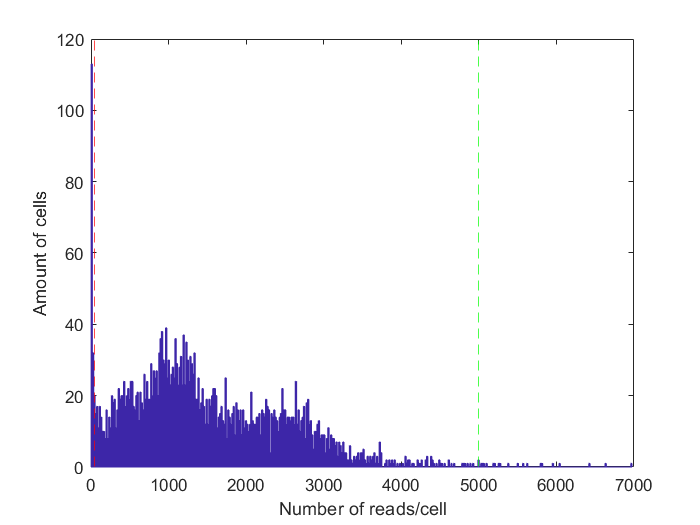

Number of cells filtered out: 182
Final number of genes included:  107
Final number of cells/bins included: 3280


BINS_Filtered=Filter_cells(BINS);